# RBE 501 Project

## `Paper: ``A Compact Asymmetrical Manipulator for Robotic Dentistry`

## `Symmetric Model`

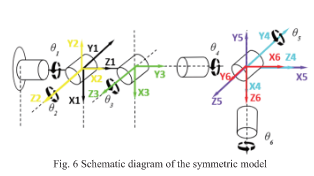

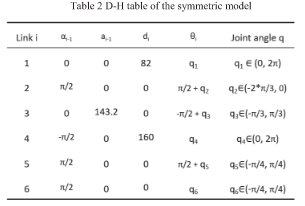

%D-H table of the symmetric model
% S_DH = [theta d a alpha]
clear;
syms q1 q2 q3 q4 q5 q6;

S_DH = [q1      0.82   0     0;
        q2+pi/2 0    0     pi/2;
        q3-pi/2 0    0.143 0;
        q4      0.160  0    -pi/2;
        q5+pi/2 0    0     pi/2;
        q6      0    0     pi/2]

$$S\_DH = \left(\begin{array}{cccc} q_{1} & \frac{41}{50} & 0 & 0\\ q_{2}+\frac{\pi }{2} & 0 & 0 & \frac{\pi }{2}\\ q_{3}-\frac{\pi }{2} & 0 & \frac{143}{1000} & 0\\ q_{4} & \frac{4}{25} & 0 & -\frac{\pi }{2}\\ q_{5}+\frac{\pi }{2} & 0 & 0 & \frac{\pi }{2}\\ q_{6} & 0 & 0 & \frac{\pi }{2} \end{array}\right)$$

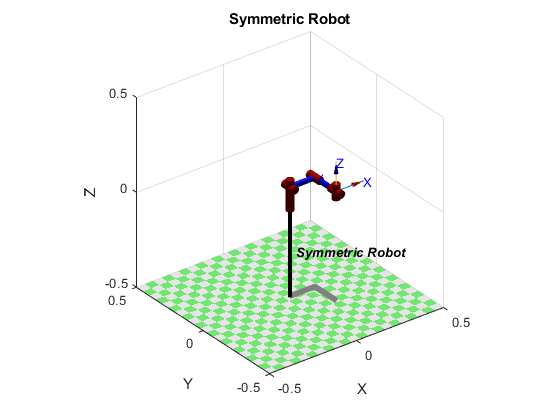


L(1) = Link([0     0.082  0   0 0]);
L(2) = Link([pi/2  0   0   pi/2 0]);
L(3) = Link([-pi/2 0   0.143 0 0]);
L(4) = Link([0     0.160 0   pi/2 0]);
L(5) = Link([pi/2  0   0   pi/2 0]); 
L(6) = Link([0     0   0   pi/2 0]);

Robot = SerialLink(L);
Robot.name = 'Symmetric Robot';

plot(Robot,[0 0 0 0 0 0], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);
title('Symmetric Robot')

## Asymmetric Model

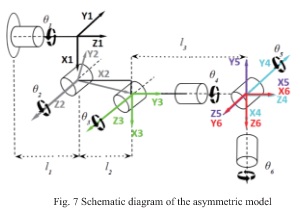

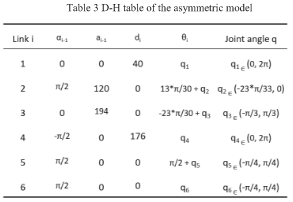

 % D-H table of the asymmetric model
% AS_DH = [theta d a alpha]
syms q1 q2 q3 q4 q5 q6;

% AS_DH_from_paper = [q1      0.040   0     0;
%                   q2+13*pi/30 0    0.120     pi/2;
%                   q3-23*pi/30 0    0.194 0;
%                   q4      0.176  0    -pi/2;
%                   q5+pi/2 0    0     pi/2;
%                   q6      0    0     pi/2]

AS_DH =[q1          0.040 0     pi/2;
        q2+13*pi/30 0     0.120 0;
        q3-23*pi/30 0     0.194 -pi/2;
        q4          0.176 0     pi/2;
        q5+pi/2     0     0     pi/2;
        q6          0     0     0]

$$AS\_DH = \left(\begin{array}{cccc} q_{1} & \frac{1}{25} & 0 & \frac{\pi }{2}\\ q_{2}+\frac{13\,\pi }{30} & 0 & \frac{3}{25} & 0\\ q_{3}-\frac{23\,\pi }{30} & 0 & \frac{97}{500} & -\frac{\pi }{2}\\ q_{4} & \frac{22}{125} & 0 & \frac{\pi }{2}\\ q_{5}+\frac{\pi }{2} & 0 & 0 & \frac{\pi }{2}\\ q_{6} & 0 & 0 & 0 \end{array}\right)$$

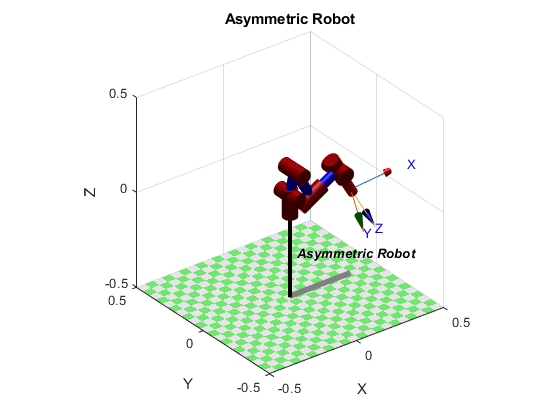


L(1) = Link('d', 0.04, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(2) = Link('d', 0, 'a', 0.12, 'alpha', 0, 'offset', (13/30)*pi);
L(3) = Link('d', 0, 'a', 0.194, 'alpha', -pi/2, 'offset', -(23/30)*pi);
L(4) = Link('d', 0.176, 'a', 0, 'alpha', pi/2, 'offset', 0);
L(5) = Link('d', 0, 'a', 0, 'alpha', pi/2, 'offset', pi/2); 
L(6) = Link('d', 0, 'a', 0, 'alpha', 0, 'offset', 0);
L(7) = Link('d', 0.15, 'a', 0, 'alpha', 0, 'offset', 0);
As_Robot = SerialLink(L);
As_Robot.name = 'Asymmetric Robot';

plot(As_Robot,[0 0 0 0 0 0 0.5], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);
title('Asymmetric Robot')


% Workspace of the Asymmetric Robot for different values of theta
th1 = 0;
th2 = -(23/33)*pi:0.05:0;
th3 = -pi/3:0.05:pi/3;
th4 = 0:0.5:2*pi;
th5 = -pi/4:0.5:pi/4;
th6 = -pi/4:0.05:pi/4;
d7 = 0.15;
q = {th1,th2,th3,th4,th5,th6};

% plotWorkspace(L,q)

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

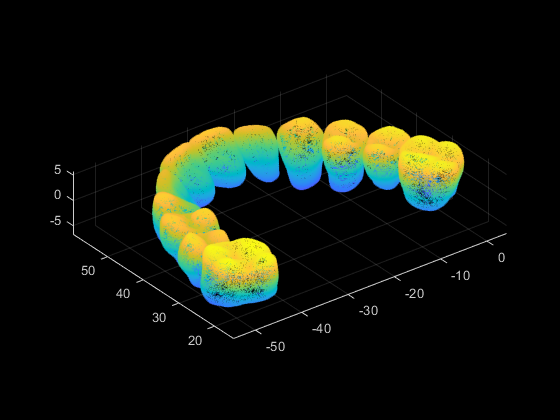

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

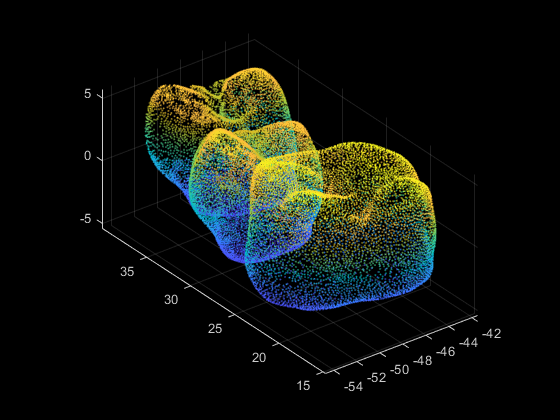


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

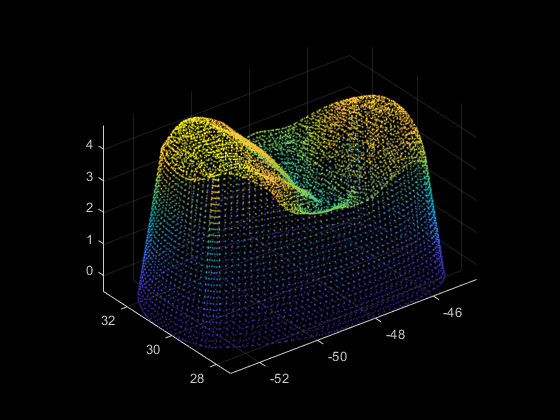


% Import and plot final model individually
stlData_fin = stlread('1tooth_mesh2.stl');
points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

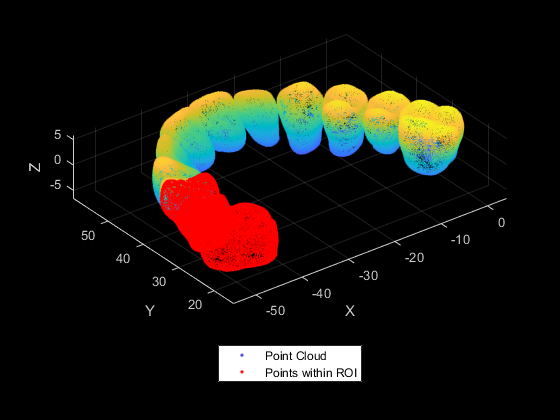


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

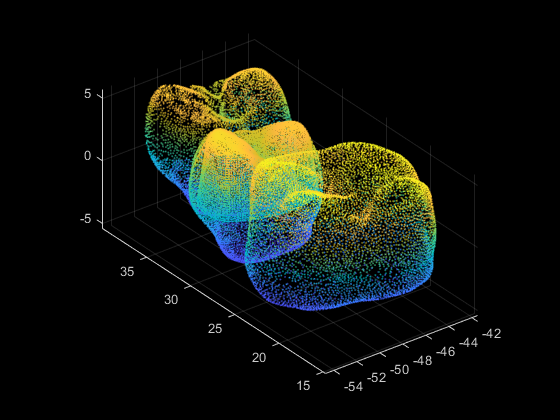


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

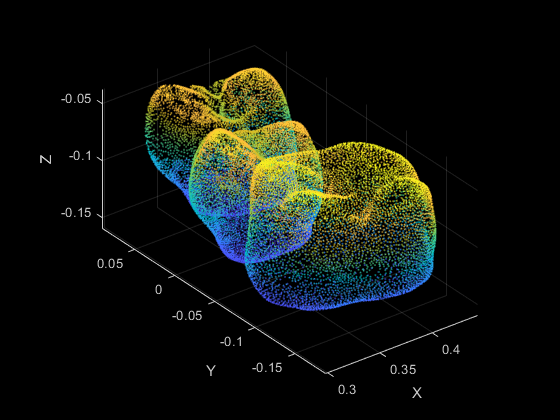


%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;
tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.9 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

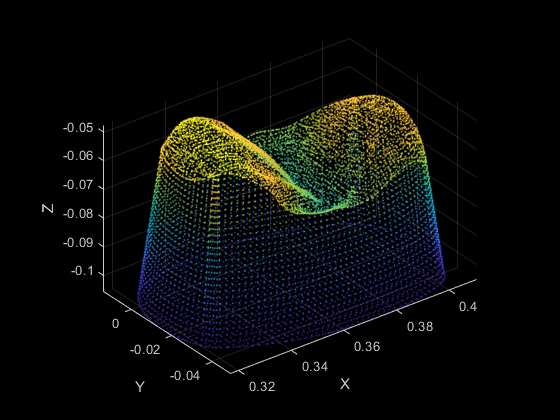

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

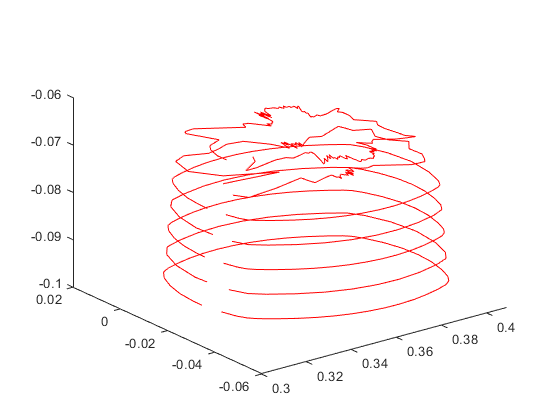

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],10);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

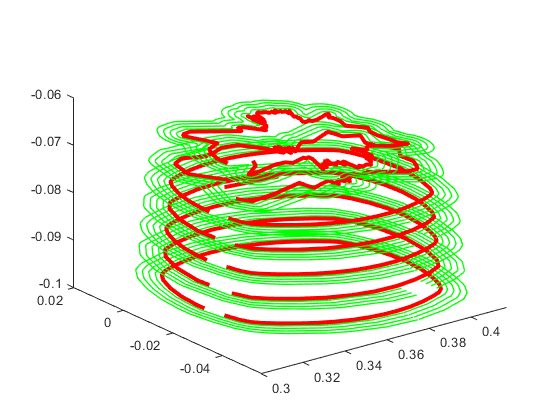

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,5);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {43×3 double}    {29×3 double}    {43×3 double}    {31×3 double}    {41×3 double}    { 81×3 double}    {164×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {189×3 double}    {313×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {143×3 double}    {228×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {126×3 double}    {183×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {115×3 double}    {153×3 double}


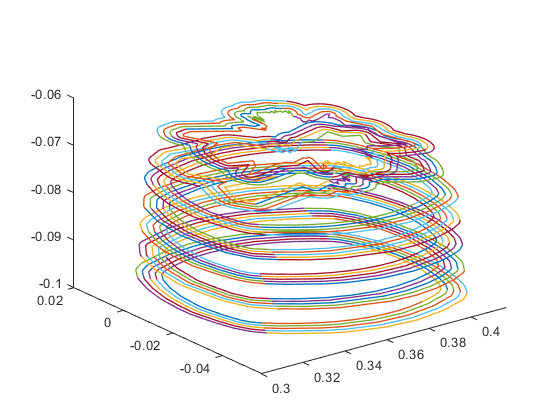

curve1 = allPoints{5,1};

figure
for i=1:7
    for j=1:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
    end
end

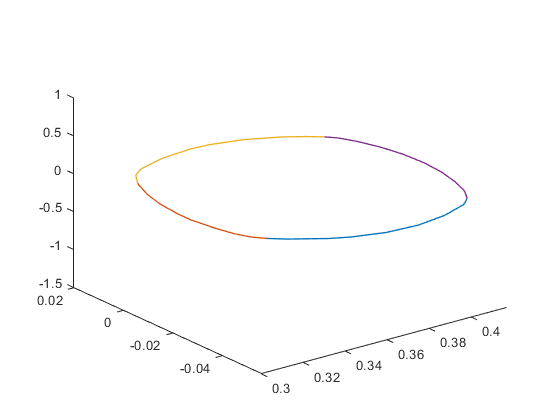

figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);

q1

q1 =     0.4063   -0.0489   -0.0975
    0.4024   -0.0511   -0.0975
    0.4011   -0.0516   -0.0975
    0.3890   -0.0546   -0.0975
    0.3751   -0.0560   -0.0975
    0.3745   -0.0560   -0.0975
    0.3604   -0.0553   -0.0975
    0.3466   -0.0524   -0.0975
    0.3392   -0.0500   -0.0975
    0.3264   -0.0441   -0.0975


## `Robot Dynamics`

figure
set(gcf,'Visible','on')
plot(As_Robot,[0 0 0 0 0 0 0.15], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5]);

hold on;
pcshow(ptCloud_3t);
scatter3(q2(1,1),q2(1,2),q2(1,3))

## `Inverse Kinematics`

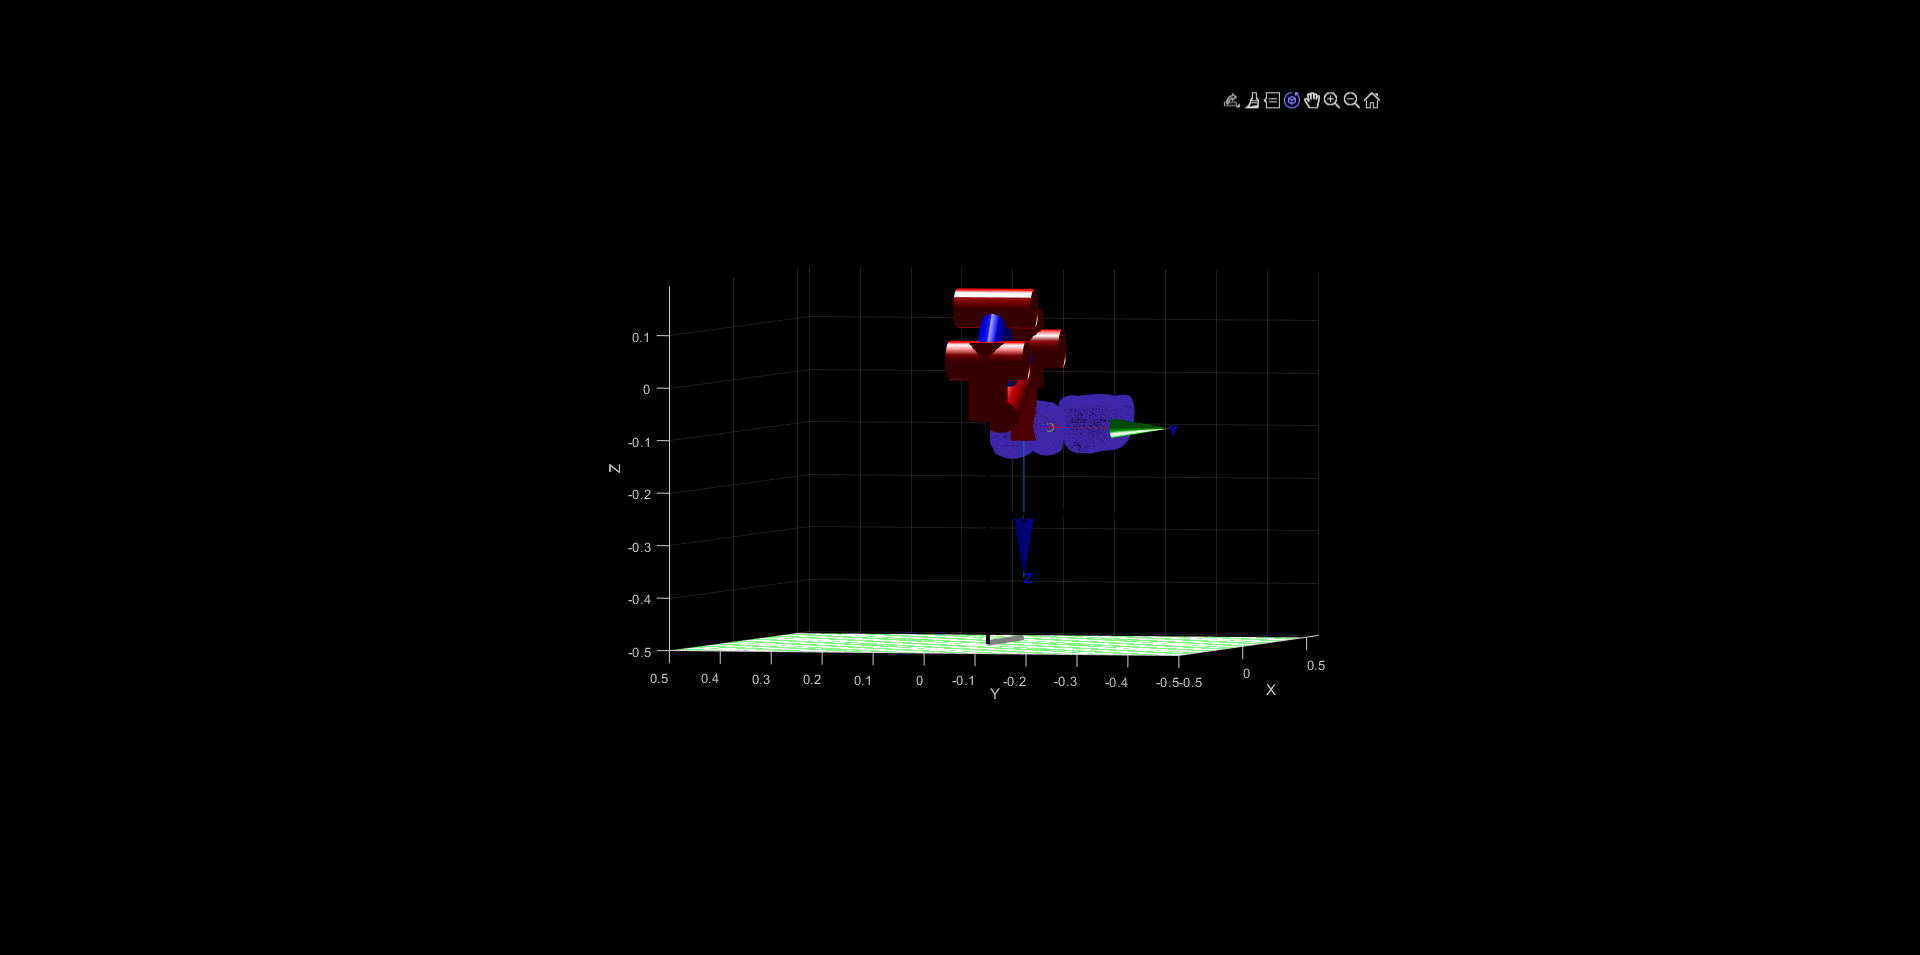

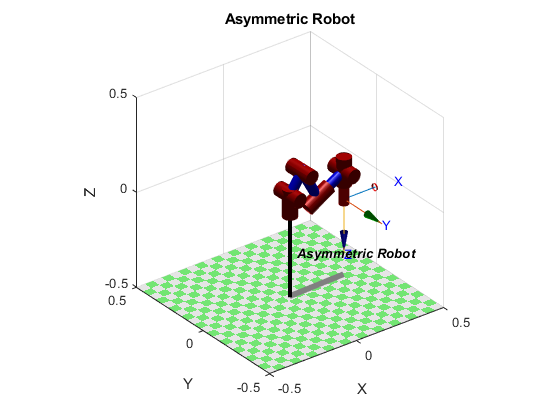

for i = 1:length(q2)
    T = transl(q2(i,1), q2(i,2), q2(1,3)) * rpy2tr(0,180,180,'deg'); 
    JAngle(i,:) = As_Robot.ikine(T,[0 0 0 0 0 0 0.5]);
end

for i = JAngle(:,1)
    for j = JAngle(:,2)
        for k = JAngle(:,3)
            for l = JAngle(:,4)
                for m = JAngle(:,5)
                    for n = JAngle(:,6)
                        for o = JAngle(:,7)
                            set(gcf,'Visible','on')
                            As_Robot.plot([i j k l m n o], 'workspace', [-0.5 0.5 -0.5 0.5 -0.5 0.5])
                            pause(0.05) 
                        end
                    end
                end
            end
        end
    end
    
end

## `Helper Functions`

### `plotWorkspace`

function plotWorkspace(DH,q)
    % drawworkspace
    %{
    This function plots a workspace for a planar n-DOF revolute or prismatic
    given DH parameters and the constraints of all variables.
    
    This function uses Robotics Toolbox by Peter Corke which can be
    downloaded from :
    https://petercorke.com/wordpress/toolboxes/robotics-toolbox
    ----------------------------------------------
    Inputs
    DH    DH parameters each row is a link
    q     a cell input contains constraints for all variables
            ordered from first link to last link.
    ---------------------------------------------------------------------
    Example
    a1 = 0.5; 
    a2 = 0.3; 
    a3 = 0.2;
    DH(1) = Link([0 0 a1 0]);
    DH(2) = Link([0 0 a2 0]);
    DH(3) = Link([0 0 a3 0]);
    th1 = (-pi/6:0.05:pi/6) ;
    th2 = (-2*pi/3:0.05:2*pi/3);
    th3 = (-pi/2:0.05:pi/2) ;
    q = {th1,th2,th3};
    
    All copyrights go to Mohammad Al-Fetyani
    University of Jordan
    %}
    
    % L = Link([Th d a alpha])
    r = SerialLink(DH);
    r.display();
    [~,n] = size(DH);
    
    
    var = sym('q',[n 1]);
    assume(var,'real')
    
    % generate a grid of theta1 and theta2,3,4 values
    [Q{1:numel(q)}] = ndgrid(q{:});
    T = simplify(vpa(r.fkine(sym(var)),3));
    Pos = T.tv;
    x(var(:)) = Pos(1);
    X = matlabFunction(x);
    X = X(Q{:});
    y(var(:)) = Pos(2);
    Y = matlabFunction(y);
    Y = Y(Q{:});
    z(var(:)) = Pos(3);
    Z = matlabFunction(z);
    Z = Z(Q{:});
    plot3(X(:),Y(:),Z(:),'r.')
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
end

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `createFit1`

function [fitresult, gof, yData, xData] = createFit1(b1, a1)
    %CREATEFIT1(B1,A1)
    %  Create a fit.
    %
    %  Data for 'untitled fit 1' fit:
    %      X Input : b1
    %      Y Output: a1
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 14-Nov-2021 06:56:48
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( b1, a1 );
    
    % Set up fittype and options.
    ft = fittype( 'smoothingspline' );
    opts = fitoptions( 'Method', 'SmoothingSpline' );
    opts.Normalize = 'on';
    opts.SmoothingParam = 0.997023529294237;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    % Plot fit with data.
    figure( 'Name', 'untitled fit 1' );
    h = plot( fitresult, xData, yData );
    legend( h, 'a1 vs. b1', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
    % Label axes
    xlabel( 'b1', 'Interpreter', 'none' );
    ylabel( 'a1', 'Interpreter', 'none' );
    grid on
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
    curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end